function indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,trainingOrthology, standardize,input_type)

## Ecoli_yeh

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_yeh.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'nature_ecoli';
standardize = '';

summaryTable = 1×11 table
    min    median    max    range     mean        std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    ___    ______    ___    _____    _______    _______    ________________    ____________    _______________    _______________    __________

    -1       0        2       3      0.19608    0.91987          153                40               60                true            0.0005  


drugList = 20×1 cell array
    {'AMIKACIN'       }
    {'AMP'            }
    {'BAC'            }
    {'BLM'            }
    {'CEF'            }
    {'CHLORAMPHENICOL'}
    {'CIPROFLOXACIN'  }
    {'DOX'            }
    {'ERYTHROMYCIN'   }
    {'FUSIDICACID'    }
    {'NAL'            }
    {'NIT'            }
    {'SM'             }
    {'SMM'            }
    {'SPECTINOMYCIN'  }
    {'SPM'            }
    {'SPT'            }
    {'TET'            }
    {'TOB'            }
    {'TRIMETHOPRIM'   }


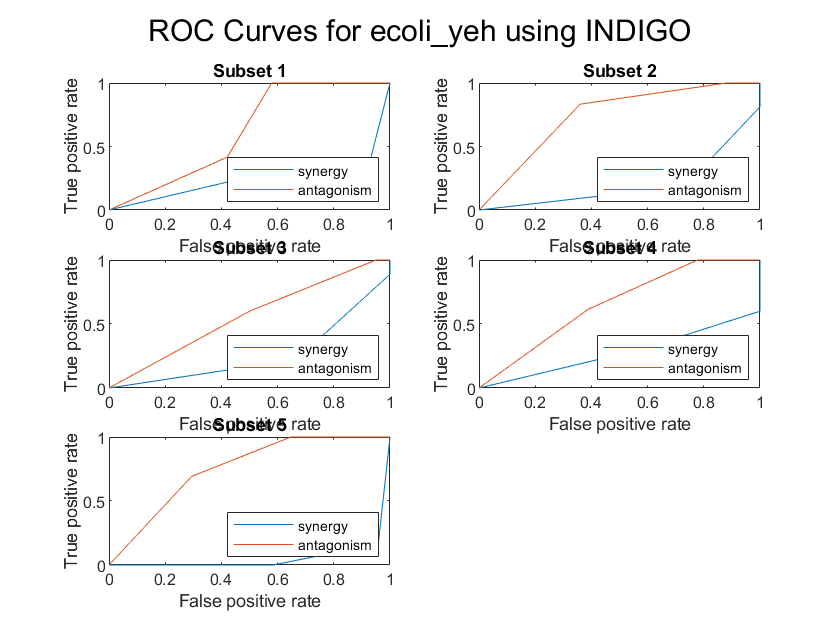

[summary,drugList] = dataExplore(testFile);

files = dataFiles();
compareFiles = [testFile;files.natureData(1:2)];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 5×4 table
    Drug 1    Drug 2    ecoli_yeh score    ecoli_bw25113 score
    ______    ______    _______________    ___________________

    "SPM"     "TOB"            0                  0.68302     
    "DOX"     "TOB"            0                 -0.21608     
    "SMM"     "BLM"            0                -0.095806     
    "NIT"     "TOB"           -1                 -0.21599     
    "NIT"     "BLM"            0                 -0.19355     


sharedInteractionsPreview = 5×4 table
    Drug 1    Drug 2    ecoli_yeh score    ecoli_iAi1 score
    ______    ______    _______________    ________________

    "SPM"     "TOB"            0               0.042195    
    "DOX"     "TOB"            0               -0.17607    
    "SMM"     "BLM"            0               -0.25463    
    "NIT"     "TOB"           -1               -0.66284    
    "NIT"     "BLM"            0                 -0.319    


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    ecoli_iAi1 score
    ______    ______    ___________________    ________________

    "A22"     "ATM"          -0.11682              -0.23949    
    "A22"     "BLM"          -0.18842              -0.22326    
    "A22"     "MMC"          -0.15416              0.081189    
    "A22"     "PUR"           0.10034               0.10767    
    "A22"     "PYO"           0.28322             -0.082868    
    "A22"     "RIF"          0.099699               0.17919    
    "AMK"     "AZM"           0.20244              0.039346    
    "AMK"     "BZK"           0.40112              0.082268    


interactionCounts = 3×3 table
                     ecoli_yeh    ecoli_bw25113    ecoli_iAi1
                     _________    _____________    __________

    ecoli_yeh            0              5               5    
    ecoli_bw25113        0              0             316    
    ecoli_iAi1           0              0               0    


R_values = 3×3 table
                     ecoli_yeh    ecoli_bw25113    ecoli_iAi1
                     _________    _____________    __________

    ecoli_yeh            0           0.35355        0.70711  
    ecoli_bw25113        0                 0        0.64896  
    ecoli_iAi1           0                 0              0  


P_values = 3×3 table
                     ecoli_yeh    ecoli_bw25113    ecoli_iAi1
                     _________    _____________    __________

    ecoli_yeh            0             0.8            0.4    
    ecoli_bw25113        0               0              0    
    ecoli_iAi1           0               0              0    


%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,standardize);

Run 1
Elapsed time is 21.210273 seconds.
Run 2
Elapsed time is 14.575274 seconds.
Run 3
Elapsed time is 13.420229 seconds.
Run 4
Elapsed time is 14.134618 seconds.
Run 5
Elapsed time is 13.515464 seconds.


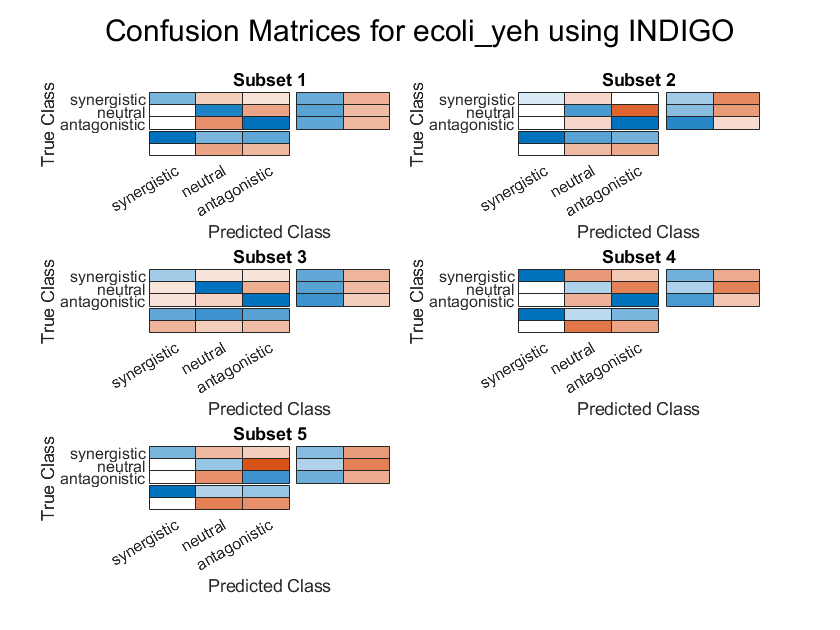

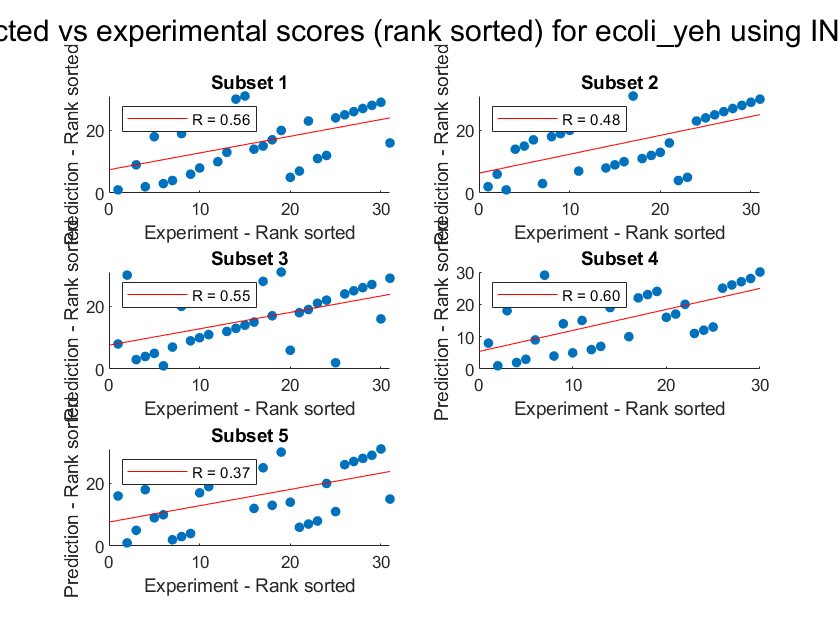

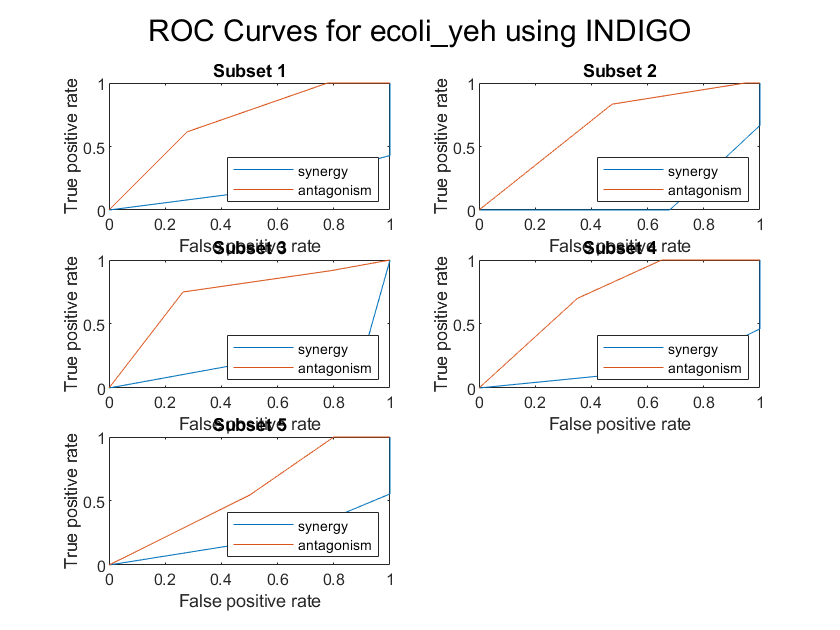

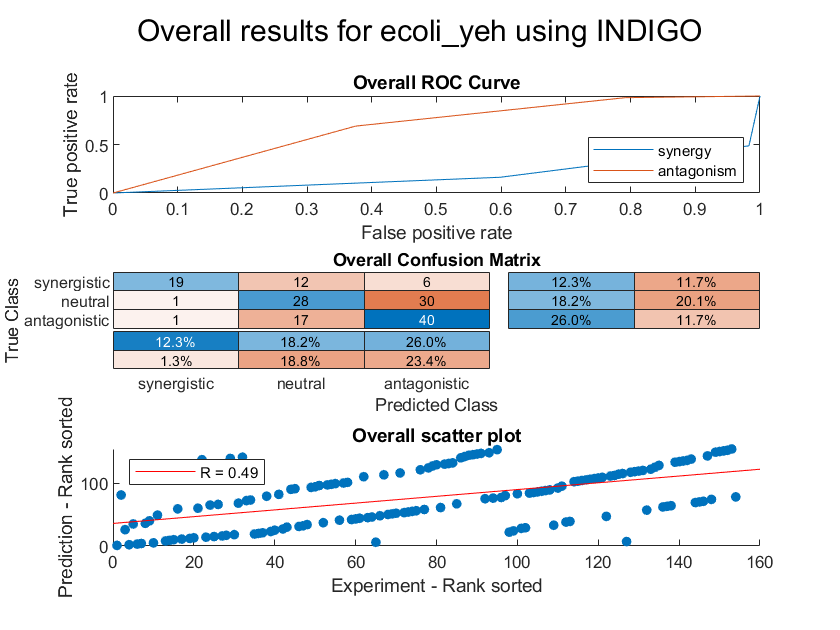

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                  Value  
                                _________

    Interactions                     30.8
    R (rank)                      0.51216
    P value                     0.0097473
    Accuracy                      0.56473
    Absolute error                0.48086
    Precision (synergy)              0.92
    Recall (synergy)              0.49753
    Precision (antagonism)        0.53191
    Recall (antagonism)           0.68883
    Mean Guess Error             -0.29671
    Guess Accuracy (p value)     0.011574
    AUC - ROC (synergy)           0.17468
    AUC - ROC (antagonism)        0.68609


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       154
    R (rank)                       0.49457
    P value                     7.0697e-11
    Accuracy                       0.56494
    Absolute error                 0.48052
    Precision (synergy)            0.90476
    Recall (synergy)               0.51351
    Precision (antagonism)         0.52632
    Recall (antagonism)            0.68966
    Mean Guess Error              -0.29273
    Guess Accuracy (p value)    3.3336e-15
    AUC - ROC (synergy)            0.18596
    AUC - ROC (antagonism)         0.68427


%analysis
[stats,averages,overview] = analyze(indigoSummary);


%save results
save(saveIndigo(indigoSummary))

testFile = 'ecoli_yeh.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'nature_ecoli';
standardize = 'standardized';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 22.547444 seconds.
Run 2
Elapsed time is 20.052067 seconds.
Run 3
Elapsed time is 44.765036 seconds.
Run 4
Elapsed time is 33.430250 seconds.
Run 5
Elapsed time is 72.343931 seconds.


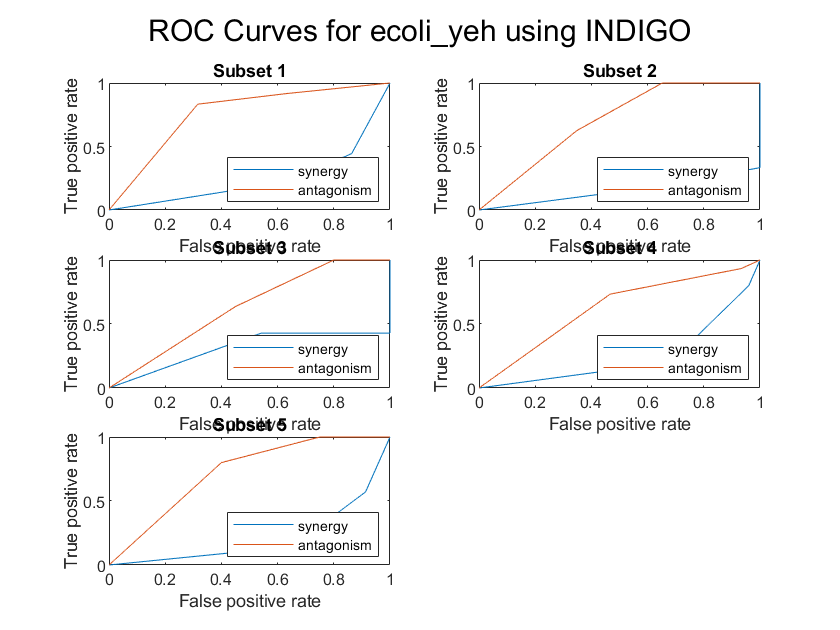

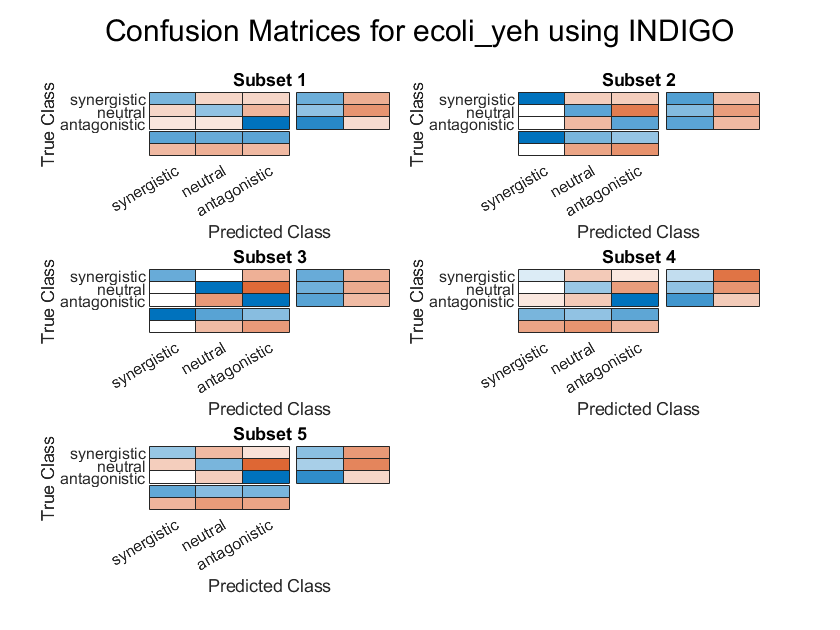

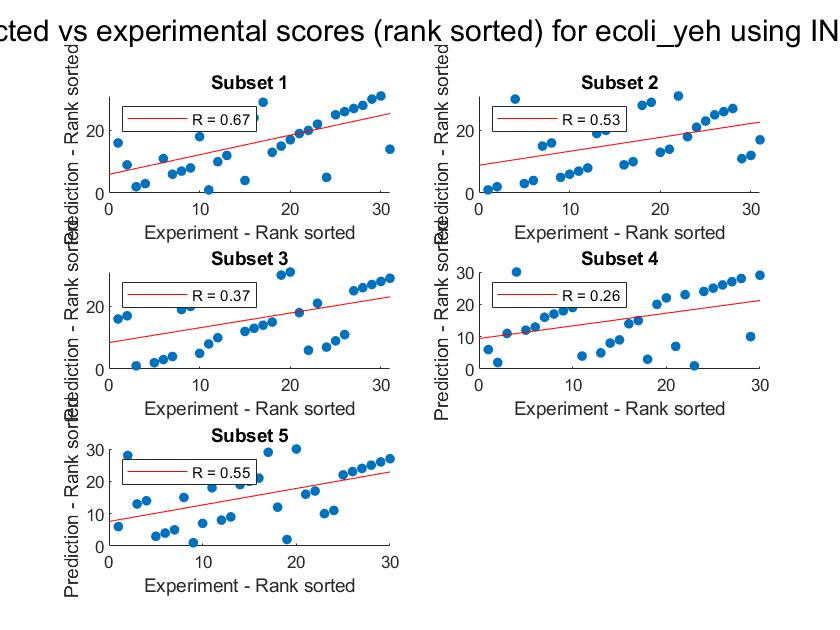

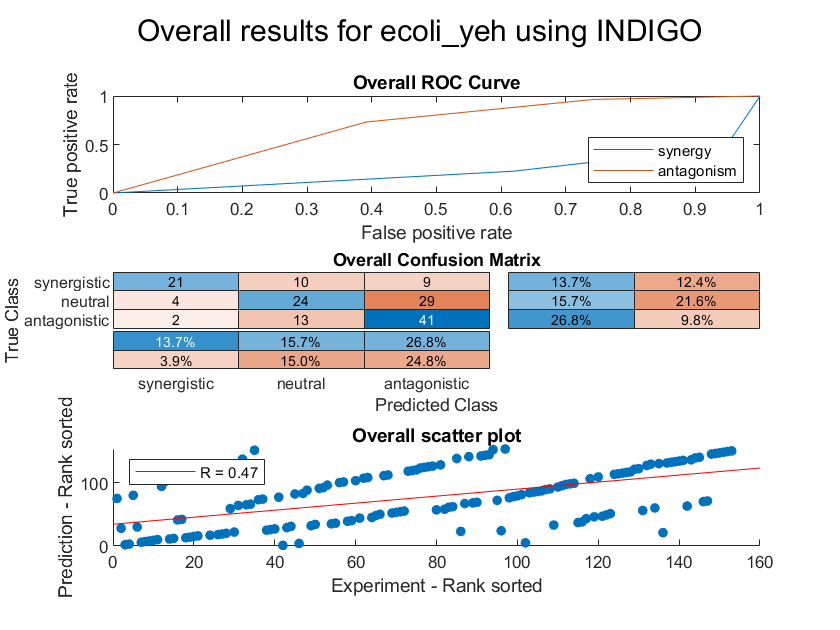

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                  Value  
                                _________

    Interactions                     30.6
    R (rank)                      0.47516
    P value                      0.041541
    Accuracy                      0.56151
    Absolute error                0.51011
    Precision (synergy)             0.745
    Recall (synergy)              0.48444
    Precision (antagonism)        0.51165
    Recall (antagonism)           0.72561
    Mean Guess Error             -0.29141
    Guess Accuracy (p value)    0.0011676
    AUC - ROC (synergy)           0.23261
    AUC - ROC (antagonism)        0.68875


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       153
    R (rank)                       0.46579
    P value                     1.3017e-09
    Accuracy                       0.56209
    Absolute error                  0.5098
    Precision (synergy)            0.77778
    Recall (synergy)                 0.525
    Precision (antagonism)         0.51899
    Recall (antagonism)            0.73214
    Mean Guess Error              -0.29569
    Guess Accuracy (p value)    1.9816e-17
    AUC - ROC (synergy)            0.22345
    AUC - ROC (antagonism)         0.69385


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_yeh.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_bw25113.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,standardize);

Run 1
Elapsed time is 33.448804 seconds.
Run 2
Elapsed time is 34.334530 seconds.
Run 3
Elapsed time is 33.429372 seconds.
Run 4
Elapsed time is 34.293499 seconds.
Run 5
Elapsed time is 34.791844 seconds.


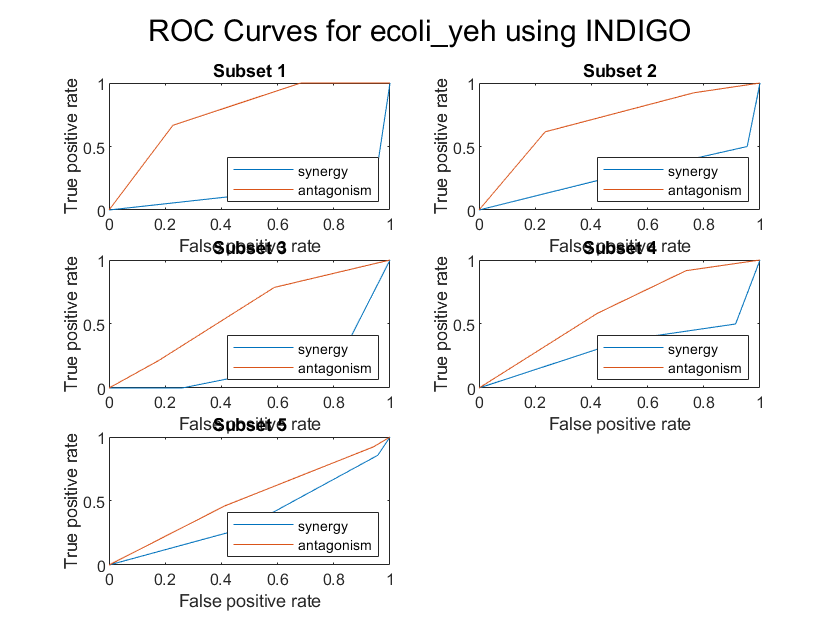

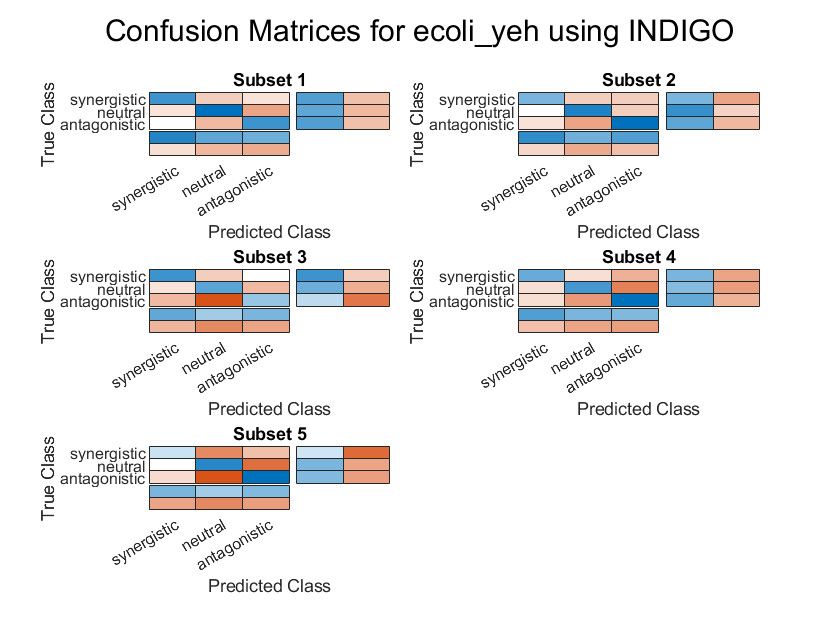

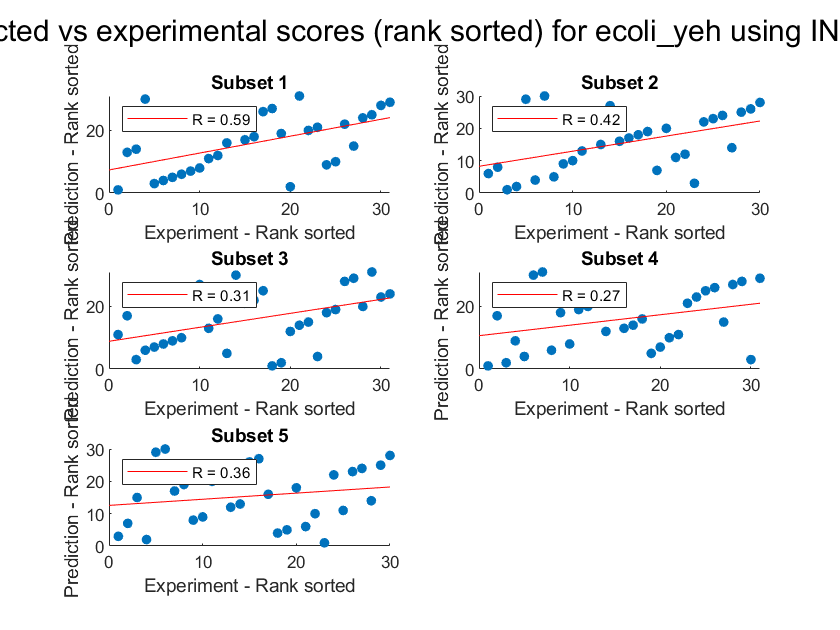

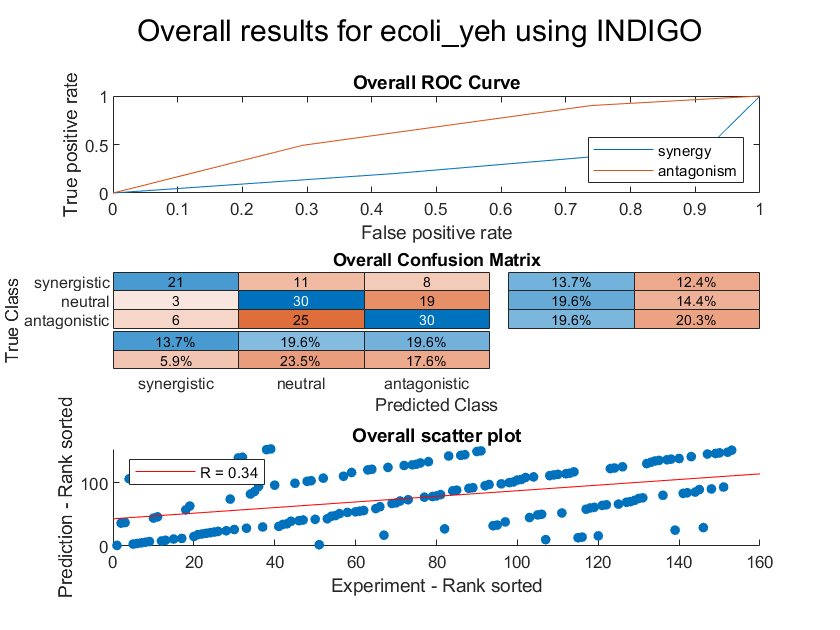

resultsTable = 5×13 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    __________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                    30.6
    R (rank)                     0.39019
    P value                     0.060951
    Accuracy                     0.52925
    Absolute error               0.56237
    Precision (synergy)          0.68476
    Recall (synergy)              0.5119
    Precision (antagonism)       0.52807
    Recall (antagonism)          0.50824
    Mean Guess Error            -0.52925
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.26813
    AUC - ROC (antagonism)        0.6402


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       153
    R (rank)                       0.34053
    P value                     1.6546e-05
    Accuracy                       0.52941
    Absolute error                 0.56209
    Precision (synergy)                0.7
    Recall (synergy)                 0.525
    Precision (antagonism)         0.52632
    Recall (antagonism)             0.4918
    Mean Guess Error              -0.52941
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.26637
    AUC - ROC (antagonism)          0.6307


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'ecoli_yeh.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_iAi1.xlsx';
trainingOrthology = 'ecoli_iAi1_orthologs.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,trainingOrthology,standardize);

Run 1
Elapsed time is 155.665050 seconds.
Run 2
Elapsed time is 138.859543 seconds.
Run 3
Elapsed time is 94.387709 seconds.
Run 4
Elapsed time is 97.098542 seconds.
Run 5
Elapsed time is 97.305948 seconds.


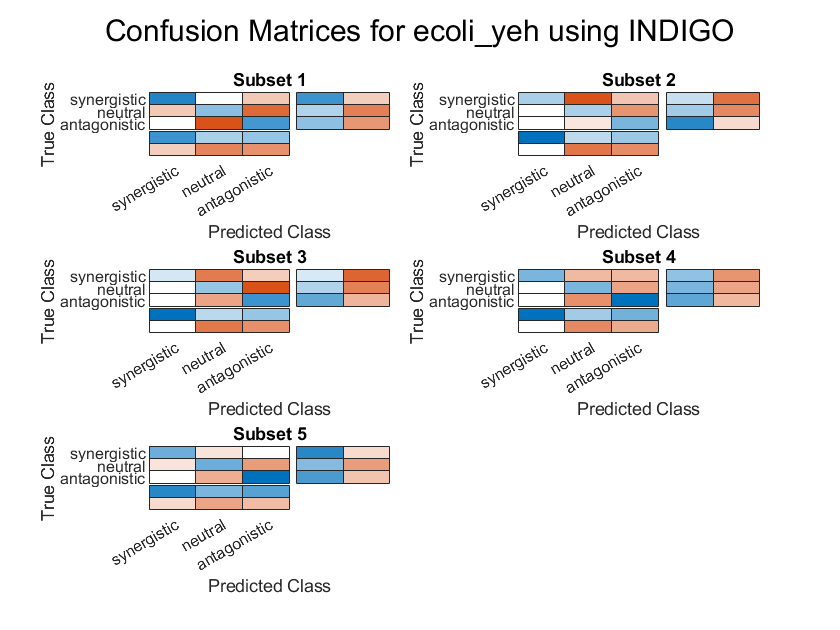

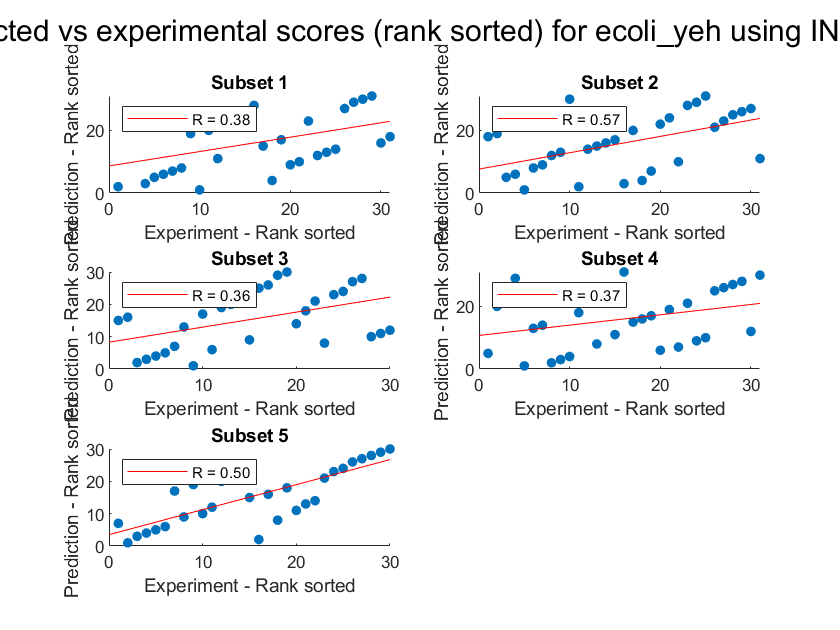

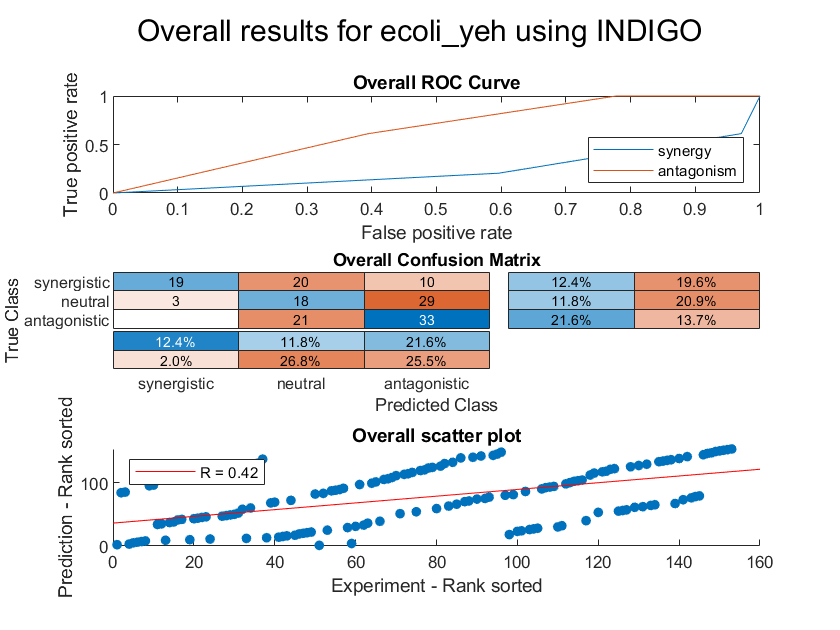

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                    30.6
    R (rank)                     0.43595
    P value                     0.027031
    Accuracy                     0.45785
    Absolute error                0.6071
    Precision (synergy)          0.91667
    Recall (synergy)             0.45639
    Precision (antagonism)       0.45859
    Recall (antagonism)          0.63154
    Mean Guess Error            -0.19646
    Guess Accuracy (p value)     0.12708
    AUC - ROC (synergy)          0.20366
    AUC - ROC (antagonism)       0.66733


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       153
    R (rank)                       0.42361
    P value                     4.8707e-08
    Accuracy                       0.45752
    Absolute error                 0.60784
    Precision (synergy)            0.86364
    Recall (synergy)               0.38776
    Precision (antagonism)         0.45833
    Recall (antagonism)            0.61111
    Mean Guess Error              -0.18725
    Guess Accuracy (p value)    4.9583e-08
    AUC - ROC (synergy)            0.23715
    AUC - ROC (antagonism)          0.6518


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))